clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/control/");
data_dir2 = fullfile(pwd,"data/hra/dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

## Plot sample data

x1 = readtable(fullfile(data_dir1,fnames_hc(1).name));
x2 = readtable(fullfile(data_dir2,fnames_ad(1).name));
num_id = 32;

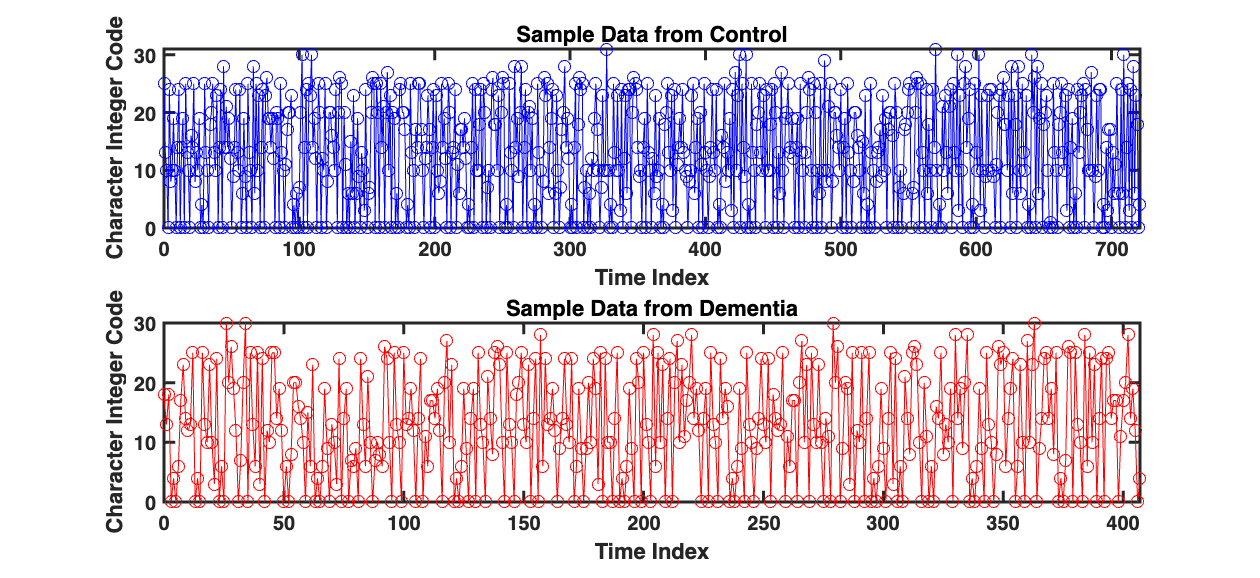

figure('Color','w','Position',[100,100,1200,550])
subplot(2,1,1)
plot(x1.index,x1.x,'-o','Color','blue')
axis tight
title("Sample Data from Control")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(2,1,2)
plot(x2.index,x2.x,'-o','Color','red')
axis tight
title("Sample Data from Dementia")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

for i=0:(num_id-1)
    id_idx = find(x1.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 150
ID 2: 1
ID 3: 0
ID 4: 9
ID 5: 17
ID 6: 0
ID 7: 31
ID 8: 8
ID 9: 11
ID 10: 13
ID 11: 80
ID 12: 7
ID 13: 12
ID 14: 38
ID 15: 44
ID 16: 2
ID 17: 6
ID 18: 15
ID 19: 16
ID 20: 32
ID 21: 44
ID 22: 6
ID 23: 0
ID 24: 35
ID 25: 46
ID 26: 62
ID 27: 12
ID 28: 4
ID 29: 10
ID 30: 1
ID 31: 8
ID 32: 2


for i=0:(num_id-1)
    id_idx = find(x2.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 85
ID 2: 0
ID 3: 0
ID 4: 6
ID 5: 10
ID 6: 0
ID 7: 24
ID 8: 4
ID 9: 7
ID 10: 14
ID 11: 35
ID 12: 6
ID 13: 11
ID 14: 22
ID 15: 31
ID 16: 1
ID 17: 3
ID 18: 9
ID 19: 4
ID 20: 24
ID 21: 16
ID 22: 3
ID 23: 0
ID 24: 15
ID 25: 22
ID 26: 34
ID 27: 7
ID 28: 4
ID 29: 7
ID 30: 0
ID 31: 4
ID 32: 0


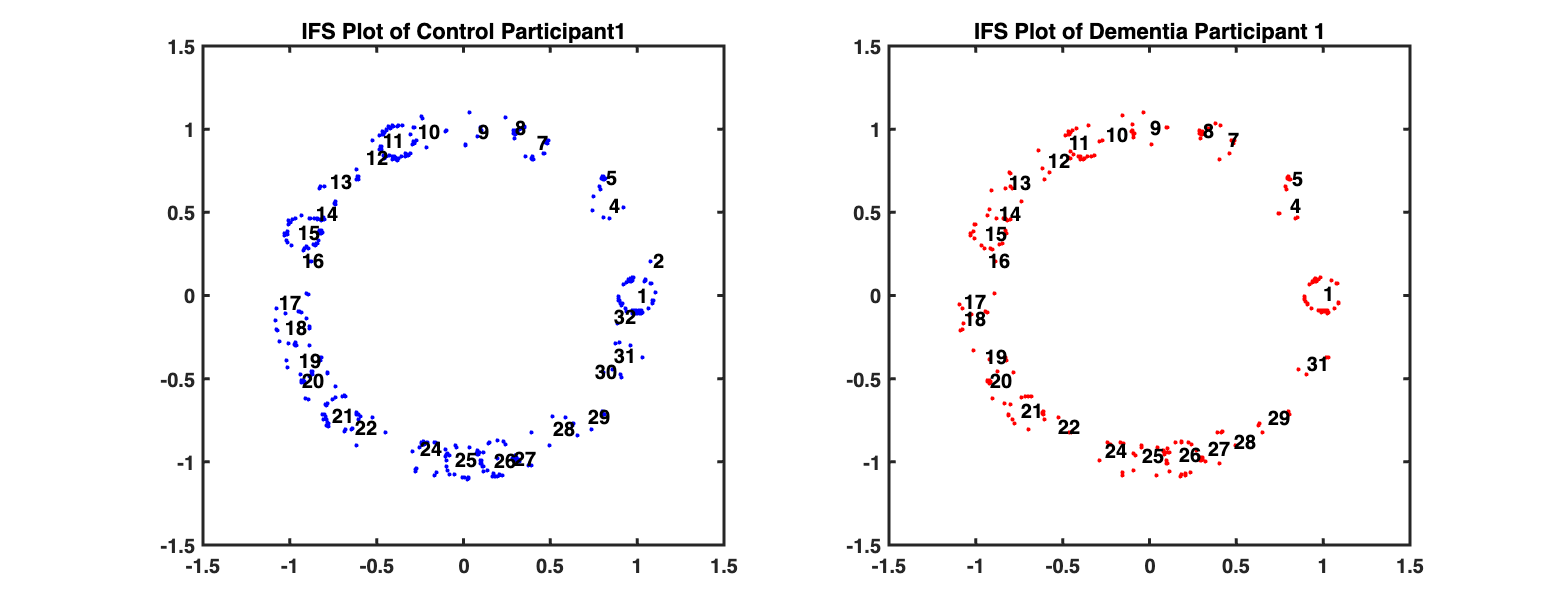

alpha = 0.1;
ifs_hc = IFS(x1.x,num_id,alpha);
ifs_ad = IFS(x2.x,num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

f = figure('Color','w','Position',[0,0,1400,550]);
subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(x1.x == (i-1));
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(x2.x == (i-1));
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

## Quantifications of IFS patterns

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);
feat_mx = NaN(fsize1+fsize2,3);

num_id = 32;
alpha = 0.04;
nbins = 10;
order = 1;

for i=1:fsize1
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    ifs_add = IFS(csig.x,num_id,alpha);
    ifs_add(1,:) = [];
    [feat_mx(i,1),feat_mx(i,2),feat_mx(i,3)] = heterorecurrence(...
        ifs_add,csig.x,order,nbins);
end

for i=1:fsize2
    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    ifs_add = IFS(csig.x,num_id,alpha);
    [feat_mx(fsize1+i,1),feat_mx(fsize1+i,2),feat_mx(fsize1+i,3)] = heterorecurrence(...
        ifs_add,csig.x,order,nbins);
end